## Clasificadores

clc; clear; close all;
rng(42); % Semilla para reproducibilidad
load('digits.mat');
[num_pixels, num_samples] = size(digits.image);  % 784 x 10000

fprintf('\n--- Evaluación de precisión (KNN y Bayes) con diferentes porcentajes de entrenamiento ---\n');


--- Evaluación de precisión (KNN y Bayes) con diferentes porcentajes de entrenamiento ---



% Aplicar PCA a todos los datos (sin normalizar, como en el ejemplo)
[coeff, score, latent] = pca(digits.image');  
d_pca = 20;  % Número fijo de componentes PCA a usar

% Vector de proporciones de entrenamiento a evaluar (10% a 90%)
ratios = 0.1:0.1:0.9;
num_ratios = length(ratios);

% Inicializar vectores para guardar la precisión media de validación cruzada
acc_knn_ratio = zeros(1, num_ratios);
acc_bayes_ratio = zeros(1, num_ratios);

% Bucle sobre cada proporción de entrenamiento
for i = 1:num_ratios
    curr_ratio = ratios(i);
    
    % Calcular el número de muestras para el subconjunto según el ratio actual
    subset_size = round(curr_ratio * num_samples);
    % Seleccionar aleatoriamente 'subset_size' índices del total
    subset_indices = randperm(num_samples, subset_size);
    
    % Extraer el subconjunto de datos (usando PCA ya calculado)
    X_subset = score(subset_indices, 1:d_pca);
    Y_subset = digits.label(subset_indices)';  % Asegurarse de que Y sea columna
    
    % Crear partición de validación cruzada (5 pliegues) sobre el subconjunto
    cv = cvpartition(subset_size, 'KFold', 5);
    
    % Inicializar vectores para guardar las precisiones de cada pliegue
    cv_knn = zeros(cv.NumTestSets, 1);
    cv_bayes = zeros(cv.NumTestSets, 1);
    
    % Bucle de validación cruzada
    for fold = 1:cv.NumTestSets
        train_idx_cv = cv.training(fold);
        test_idx_cv  = cv.test(fold);
        
        X_train_cv = X_subset(train_idx_cv, :);
        Y_train_cv = Y_subset(train_idx_cv);
        X_test_cv  = X_subset(test_idx_cv, :);
        Y_test_cv  = Y_subset(test_idx_cv);
        
        % --- Modelo KNN ---
        k = 3;
        mdl_knn = fitcknn(X_train_cv, Y_train_cv, 'NumNeighbors', k);
        Y_pred_knn = predict(mdl_knn, X_test_cv);
        cv_knn(fold) = mean(Y_pred_knn == Y_test_cv) * 100;
        
        % --- Modelo Naive Bayes ---
        mdl_bayes = fitcnb(X_train_cv, Y_train_cv);
        Y_pred_bayes = predict(mdl_bayes, X_test_cv);
        cv_bayes(fold) = mean(Y_pred_bayes == Y_test_cv) * 100;
    end
    
    % Precisión media en validación cruzada para el ratio actual
    acc_knn_ratio(i) = mean(cv_knn);
    acc_bayes_ratio(i) = mean(cv_bayes);
    
    fprintf('Entrenamiento %.0f%% -> KNN: %.2f%%, Bayes: %.2f%%\n', ...
            curr_ratio*100, acc_knn_ratio(i), acc_bayes_ratio(i));
end

Entrenamiento 10% -> KNN: 89.80%, Bayes: 82.90%
Entrenamiento 20% -> KNN: 91.45%, Bayes: 84.00%
Entrenamiento 30% -> KNN: 92.90%, Bayes: 83.67%
Entrenamiento 40% -> KNN: 93.00%, Bayes: 84.15%
Entrenamiento 50% -> KNN: 94.32%, Bayes: 84.54%
Entrenamiento 60% -> KNN: 93.40%, Bayes: 84.23%
Entrenamiento 70% -> KNN: 94.00%, Bayes: 84.31%
Entrenamiento 80% -> KNN: 94.71%, Bayes: 84.71%
Entrenamiento 90% -> KNN: 94.77%, Bayes: 84.59%


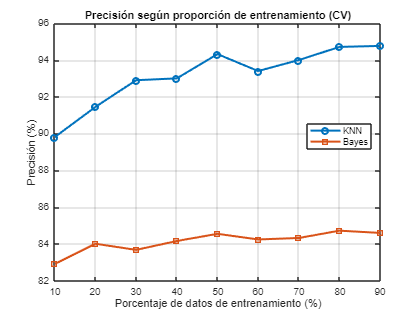


% Graficar resultados
figure;
plot(ratios*100, acc_knn_ratio, '-o', 'LineWidth', 2, 'DisplayName', 'KNN');
hold on;
plot(ratios*100, acc_bayes_ratio, '-s', 'LineWidth', 2, 'DisplayName', 'Bayes');
xlabel('Porcentaje de datos de entrenamiento (%)');
ylabel('Precisión (%)');
title('Precisión según proporción de entrenamiento (CV)');
legend('Location','best');
grid on;